# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `net`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 08-Sep-2025 15:04:24

## Create dlnetwork

Create the dlnetwork variable to contain the network layers.

net = dlnetwork;

## Add Layer Branches

Add branches to the dlnetwork. Each branch is a linear array of layers.

tempNet = [
    imageInputLayer([1096 715 102],"Name","imageinput")
    convolution2dLayer([3 3],128,"Name","conv_1","Padding","same")];
net = addLayers(net,tempNet);

tempNet = averagePooling2dLayer([5 5],"Name","avgpool2d","Padding","same");
net = addLayers(net,tempNet);

tempNet = [
    convolution2dLayer([3 3],64,"Name","conv","Padding","same")
    maxPooling2dLayer([3 3],"Name","maxpool","Padding","same")
    batchNormalizationLayer("Name","batchnorm")];
net = addLayers(net,tempNet);

tempNet = [
    convolution2dLayer([1 1],64,"Name","conv_2","Padding","same")
    reluLayer("Name","relu")];
net = addLayers(net,tempNet);

tempNet = [
    depthConcatenationLayer(3,"Name","depthcat")
    averagePooling2dLayer([5 5],"Name","avgpool2d_1","Padding","same")];
net = addLayers(net,tempNet);

tempNet = [
    convolution2dLayer([3 3],64,"Name","conv_8","Padding","same")
    maxPooling2dLayer([3 3],"Name","maxpool_1","Padding","same")
    batchNormalizationLayer("Name","batchnorm_1")];
net = addLayers(net,tempNet);

tempNet = [
    convolution2dLayer([1 1],64,"Name","conv_9","Padding","same")
    reluLayer("Name","relu_4")];
net = addLayers(net,tempNet);

tempNet = averagePooling2dLayer([5 5],"Name","avgpool2d_2","Padding","same");
net = addLayers(net,tempNet);

tempNet = [
    convolution2dLayer([3 3],64,"Name","conv_10","Padding","same")
    maxPooling2dLayer([3 3],"Name","maxpool_2","Padding","same")
    batchNormalizationLayer("Name","batchnorm_2")];
net = addLayers(net,tempNet);

tempNet = [
    convolution2dLayer([1 1],64,"Name","conv_11","Padding","same")
    reluLayer("Name","relu_5")];
net = addLayers(net,tempNet);

tempNet = depthConcatenationLayer(2,"Name","depthcat_2");
net = addLayers(net,tempNet);

tempNet = [
    depthConcatenationLayer(3,"Name","depthcat_1")
    convolution2dLayer([1 1],64,"Name","conv_3","Padding","same")
    reluLayer("Name","relu_1")
    convolution2dLayer([1 1],64,"Name","conv_4","Padding","same")
    clippedReluLayer(3,"Name","clippedrelu")
    convolution2dLayer([1 1],64,"Name","conv_5","Padding","same")
    reluLayer("Name","relu_2")
    convolution2dLayer([1 1],32,"Name","conv_6","Padding","same")
    reluLayer("Name","relu_3")
    convolution2dLayer([1 1],9,"Name","conv_7","Padding","same")
    softmaxLayer("Name","softmax")];
net = addLayers(net,tempNet);

% clean up helper variable
clear tempNet;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

net = connectLayers(net,"conv_1","avgpool2d");
net = connectLayers(net,"conv_1","avgpool2d_2");
net = connectLayers(net,"avgpool2d","conv");
net = connectLayers(net,"avgpool2d","conv_2");
net = connectLayers(net,"avgpool2d","depthcat/in3");
net = connectLayers(net,"batchnorm","depthcat/in2");
net = connectLayers(net,"relu","depthcat/in1");
net = connectLayers(net,"avgpool2d_1","conv_8");
net = connectLayers(net,"avgpool2d_1","conv_9");
net = connectLayers(net,"batchnorm_1","depthcat_1/in2");
net = connectLayers(net,"relu_4","depthcat_1/in1");
net = connectLayers(net,"avgpool2d_2","conv_10");
net = connectLayers(net,"avgpool2d_2","conv_11");
net = connectLayers(net,"batchnorm_2","depthcat_2/in2");
net = connectLayers(net,"relu_5","depthcat_2/in1");
net = connectLayers(net,"depthcat_2","depthcat_1/in3");
net = initialize(net);

## Plot Layers

plot(net);

data = repmat(pavia,[1,1,1,2])

data = data(:,:,1,1) =

   376   447   519   305   376   376   376   376   519   376   447   376   376   376   376   447   447   376   376   376   376   376   447   447   376   376   447   447   447   376   447   376   447   376   376   376   376   305   447   305   305   305   519   376   376   376   376   376   305   376   376   447   447   447   376   447   447   376   519   447   376   447   376   376   447   305   447   447   376   376   447   376   376   305   447   376   376   376   376   376   519   447   376   363   363   434
   376   447   519   305   376   376   376   376   519   376   447   376   376   434   363   363   434   434   434   363   363   363   434   363   363   363   363   363   363   363   363   363   363   434   291   363   363   434   363   363   291   434   434   434   363   291   434   363   363   363   434   363   363   434   363   434   434   363   434   434   434   434   434   505   505   434   363   363   434   363   363   363   363   363   291   363   

labels = repmat(Y,[1,1,1,2])

labels = labels(:,:,1,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     0     0     0     0     0     0     

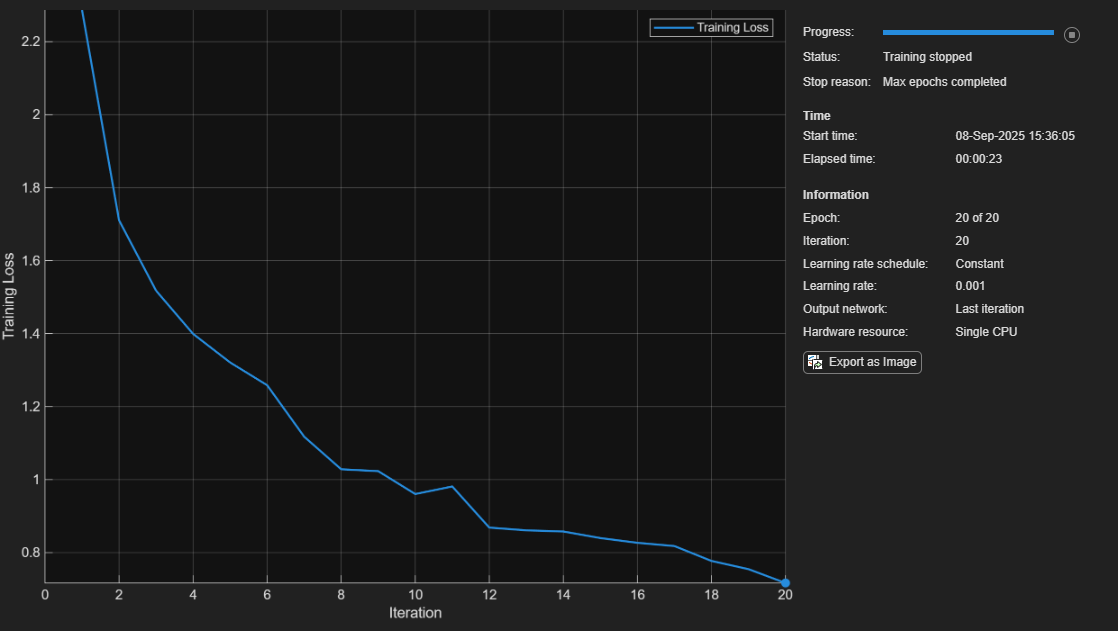


options = trainingOptions('adam', ...
    'MaxEpochs', 50, ...           % Must be 1 for one data point
    'InitialLearnRate', 1e-3, ...
    'Shuffle', 'never', ...            % No point shuffling 1 sample
    'Verbose', false, ...
    'Plots', 'training-progress');


Trainednet = trainnet(data, labels, net,"crossentropy", options);

save("TrainedNetonpavia.mat","Trainednet");